clear all
close all
clc

Ts = 1e-2

Ts = 0.0100


m1 = 1

m1 = 1

m2 = 1.2

m2 = 1.2000

k1 = 20

k1 = 20

k2 = 25

k2 = 25

k = 15

k = 15

c1 = 1

c1 = 1

c2 = 1.2

c2 = 1.2000

c = 0.8

c = 0.8000

k3 = 40

k3 = 40


syms x1 x2 x3 x4 u1 u2 w

f1 = x3

$$f1 = x_{3}$$

f2 = x4

$$f2 = x_{4}$$

f3 = (-k1*x1-c1*x3+k*(x2-x1)+k3*(x2-x1)^3+c*(x4-x3)+u1)/m1

$$f3 = u_{1}-35\,x_{1}+15\,x_{2}-\frac{9\,x_{3}}{5}+\frac{4\,x_{4}}{5}-40\,{\left(x_{1}-x_{2}\right)}^{3}$$

f4 = (-k2*x2-c2*x4-k*(x2-x1)-k3*(x2-x1)^3+c*(x4-x3)+u2)/m2

$$f4 = \frac{5\,u_{2}}{6}+\frac{25\,x_{1}}{2}-\frac{100\,x_{2}}{3}-\frac{2\,x_{3}}{3}-\frac{x_{4}}{3}+\frac{100\,{\left(x_{1}-x_{2}\right)}^{3}}{3}$$


model = [f1 f2 f3 f4]

$$model = \left(\begin{array}{cccc} x_{3} & x_{4} & u_{1}-35\,x_{1}+15\,x_{2}-\frac{9\,x_{3}}{5}+\frac{4\,x_{4}}{5}-40\,{\left(x_{1}-x_{2}\right)}^{3} & \frac{5\,u_{2}}{6}+\frac{25\,x_{1}}{2}-\frac{100\,x_{2}}{3}-\frac{2\,x_{3}}{3}-\frac{x_{4}}{3}+\frac{100\,{\left(x_{1}-x_{2}\right)}^{3}}{3} \end{array}\right)$$


f_par = subs(model,[x3 x4 u1 u2], [0 0 1 -0.5])

$$f\_par = \left(\begin{array}{cccc} 0 & 0 & 15\,x_{2}-35\,x_{1}-40\,{\left(x_{1}-x_{2}\right)}^{3}+1 & \frac{25\,x_{1}}{2}-\frac{100\,x_{2}}{3}+\frac{100\,{\left(x_{1}-x_{2}\right)}^{3}}{3}-\frac{5}{12} \end{array}\right)$$

points = solve(f_par([3 4]))

points = struct with fields:
    x1: [3×1 sym]
    x2: [3×1 sym]


x1_bar_potential = double(points.x1)

x1_bar_potential =    0.0276 + 0.0000i
   0.0028 + 0.4491i
   0.0028 - 0.4491i


x2_bar_potential = double(points.x2)

x2_bar_potential =   -0.0021 + 0.0000i
   0.0177 - 0.3593i
   0.0177 + 0.3593i



x1_bar = []


x1_bar =

     []



x2_bar = []


x2_bar =

     []




for i=1:length(x1_bar_potential)
    if(imag(x1_bar_potential(i))==0)
        x1_bar = x1_bar_potential(i)
    end
end

x1_bar = 0.0276


for j=1:length(x2_bar_potential)
    if(imag(x2_bar_potential(j))==0)
        x2_bar = x2_bar_potential(j)
    end
end

x2_bar = -0.0021


x_bar = [x1_bar x2_bar 0 0]

x_bar =     0.0276   -0.0021         0         0



A = jacobian(model,[x1 x2 x3 x4])

$$A = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ -120\,{\left(x_{1}-x_{2}\right)}^{2}-35 & 120\,{\left(x_{1}-x_{2}\right)}^{2}+15 & -\frac{9}{5} & \frac{4}{5}\\ 100\,{\left(x_{1}-x_{2}\right)}^{2}+\frac{25}{2} & -100\,{\left(x_{1}-x_{2}\right)}^{2}-\frac{100}{3} & -\frac{2}{3} & -\frac{1}{3} \end{array}\right)$$

A = double(subs(A,[x1 x2 x3 x4], x_bar))

A =          0         0    1.0000         0
         0         0         0    1.0000
  -35.1062   15.1062   -1.8000    0.8000
   12.5885  -33.4218   -0.6667   -0.3333



B = jacobian(model,[u1 u2])

$$B = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0\\ 0 & \frac{5}{6} \end{array}\right)$$

B = double(subs(B,[x1 x2 x3 x4], x_bar))

B =          0         0
         0         0
    1.0000         0
         0    0.8333



C = [1 0 0 0; 0 1 0 0]

C =      1     0     0     0
     0     1     0     0



nx = size(A,1)

nx = 4

nu = size(B,2)

nu = 2

ny = size(C,1)

ny = 2


D = zeros(ny,nu)

D =      0     0
     0     0



if any(real(eig(A))>0)
    fpritnf('Il sistema è localmente instabile\n')
else
    fprintf('Il sistema è localmente asintoticamente stabile\n')
end

Il sistema è localmente asintoticamente stabile



Mr = ctrb(A,B)

Mr =          0         0    1.0000         0   -1.8000    0.6667  -32.3995   11.1663
         0         0         0    0.8333   -0.6667   -0.2778   14.0107  -28.2034
    1.0000         0   -1.8000    0.6667  -32.3995   11.1663  122.6480  -70.2623
         0    0.8333   -0.6667   -0.2778   14.0107  -28.2034   16.5514   19.6331


Mo = obsv(A,C)

Mo =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000
  -35.1062   15.1062   -1.8000    0.8000
   12.5885  -33.4218   -0.6667   -0.3333
   73.2619  -53.9286  -32.3995   13.3995
   19.2080    1.0698   14.0107  -33.8440



if rank(Mr) ~= nx
    fprintf('Il sistema non è controllabile\n');
else
    fprintf('Il sistema è controllabile\n');
end

Il sistema è controllabile



if rank(Mo) ~= nx
    fprintf('Il sistema non è osservabile\n');
else
    fprintf('Il sistema è osservabile\n');
end

Il sistema è osservabile


poles = [-5 -5 -10 -10]

poles =     -5    -5   -10   -10



K_place = place(A,B,poles)

K_place =    14.8938   15.1062   13.2000    0.8000
   15.1062   19.8938   -0.8000   17.6000



if any(real(eig(A-B*K_place))>0)
    fpritnf('Il sistema è localmente instabile in chiuso\n')
else
    fprintf('Il sistema è localmente asintoticamente stabile in chiuso\n')
end

Il sistema è localmente asintoticamente stabile in chiuso



sys = ss(A-B*K_place,B,C,D);
Comp = pinv(dcgain(sys))

Comp =     50     0
     0    60



x0 = [0.1 0.3 0 0]

x0 =     0.1000    0.3000         0         0


xref = [0.5 1]

xref =     0.5000    1.0000


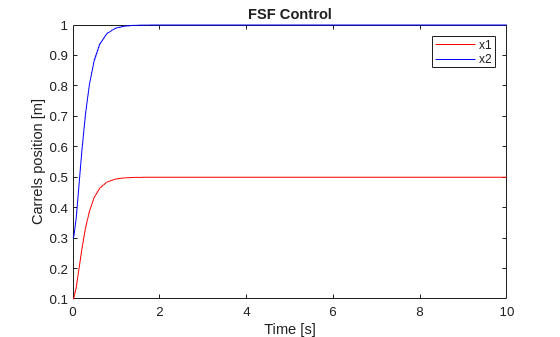


out = sim('Bait_Ambrosino_place.slx');
x1_place = out.x1.Data;
x2_place = out.x2.Data;
time = out.x1.Time;

figure
grid on
plot(time, x1_place, 'r', time, x2_place, 'b');
xlabel('Time [s]');
ylabel('Carrels position [m]');
title('FSF Control');
legend('x1', 'x2');

n_aug = 1

n_aug = 1

Tades = 0.3

Tades = 0.3000


alpha = 4/Tades

alpha = 13.3333


A_aug = [A zeros(nx,n_aug); -C(1,:) 0] + alpha*eye(nx+n_aug)

A_aug =    13.3333         0    1.0000         0         0
         0   13.3333         0    1.0000         0
  -35.1062   15.1062   11.5333    0.8000         0
   12.5885  -33.4218   -0.6667   13.0000         0
   -1.0000         0         0         0   13.3333


B_aug = [B; zeros(n_aug,nu)]

B_aug =          0         0
         0         0
    1.0000         0
         0    0.8333
         0         0


C_aug = [C zeros(ny,n_aug)]

C_aug =      1     0     0     0     0
     0     1     0     0     0


D_aug = D

D_aug =      0     0
     0     0



Q_tilde = 1

Q_tilde = 1

Q = C_aug'*Q_tilde*C_aug+blkdiag(zeros(nx,nx),1)

Q =      1     0     0     0     0
     0     1     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     1


R = eye(nu)

R =      1     0
     0     1



K_lqi = lqr(A_aug,B_aug,Q,R)

K_lqi = 1.0e+04 *

    0.2039    0.0030    0.0076    0.0001   -1.8644
    0.0092    0.0843    0.0001    0.0063   -0.0996



if any(real(eig(A_aug-B_aug*K_lqi))>0)
    fpritnf('Il sistema è localmente instabile in chiuso\n')
else
    fprintf('Il sistema è localmente asintoticamente stabile in chiuso\n')
end

Il sistema è localmente asintoticamente stabile in chiuso


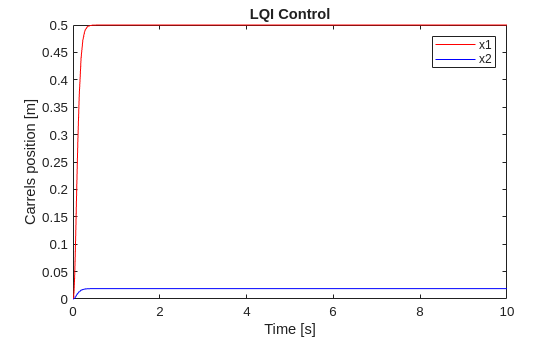


out = sim('Bait_Ambrosino_lqi.slx');
x1_lqi = out.x1.Data;
x2_lqi = out.x2.Data;
time = out.x1.Time;

figure
grid on
plot(time, x1_lqi, 'r', time, x2_lqi, 'b');
xlabel('Time [s]');
ylabel('Carrels position [m]');
title('LQI Control');
legend('x1', 'x2');

f3_w = (-k1*x1-c1*x3+k*(x2-x1)+k3*(x2-x1)^3+c*(x4-x3)+u1+w)/m1

$$f3\_w = u_{1}+w-35\,x_{1}+15\,x_{2}-\frac{9\,x_{3}}{5}+\frac{4\,x_{4}}{5}-40\,{\left(x_{1}-x_{2}\right)}^{3}$$


model_w = [f1 f2 f3_w f4]

$$model\_w = \left(\begin{array}{cccc} x_{3} & x_{4} & u_{1}+w-35\,x_{1}+15\,x_{2}-\frac{9\,x_{3}}{5}+\frac{4\,x_{4}}{5}-40\,{\left(x_{1}-x_{2}\right)}^{3} & \frac{5\,u_{2}}{6}+\frac{25\,x_{1}}{2}-\frac{100\,x_{2}}{3}-\frac{2\,x_{3}}{3}-\frac{x_{4}}{3}+\frac{100\,{\left(x_{1}-x_{2}\right)}^{3}}{3} \end{array}\right)$$


B_w = jacobian(model_w,[w u1 u2])

$$B\_w = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 1 & 0\\ 0 & 0 & \frac{5}{6} \end{array}\right)$$

B_w = double(subs(B_w,[x1 x2 x3 x4], x_bar))

B_w =          0         0         0
         0         0         0
    1.0000    1.0000         0
         0         0    0.8333



A_inf= 0.15

A_inf = 0.1500

Tades_1 = 3

Tades_1 = 3


s_perc = 60

s_perc = 60

s_l = s_perc/100

s_l = 0.6000


zeta =  -log(s_l)/(sqrt(pi^2+log(s_l)^2))

zeta = 0.1605

Mp = 1/2/zeta

Mp = 3.1154


wc= 4/Tades_1

wc = 1.3333


s = tf('s')


s =
 
  s
 
Continuous-time transfer function.



Ws = (s/Mp + wc)/(s+A_inf*wc)


Ws =
 
     s + 4.154
  ----------------
  3.115 s + 0.6231
 
Continuous-time transfer function.



Wk = 0.01900*eye(nu)

Wk =     0.0190         0
         0    0.0190



[K_h,~,gamma] = mixsyn(ss(A,B,C,zeros(ny,nu)),Ws*eye(ny),Wk,[])


K_h =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1        -0.2  -8.407e-16  -3.297e-16   4.581e-17  -2.242e-17   1.665e-17
   x2  -1.421e-15        -0.2    2.24e-16  -3.761e-16   3.055e-17   -3.92e-17
   x3  -9.902e-16   1.126e-15   1.946e-16  -2.124e-16           1  -2.481e-17
   x4  -8.337e-17   3.902e-17   4.069e-17   1.338e-17   1.922e-18           1
   x5       250.8      -196.9      -63.76       25.58      -9.979       3.676
   x6      -129.4       229.7       10.52      -56.97       1.331      -8.864
 
  B = 
               u1          u2
   x1           1  -8.972e-20
   x2   1.281e-16           1
   x3   1.188e-16  -1.193e-16
   x4   2.866e-17   1.227e-17
   x5    5.07e-16   3.599e-16
   x6  -1.452e-15   1.857e-15
 
  C = 
           x1      x2      x3      x4      x5      x6
   y1   250.8  -196.9  -28.65   10.48  -8.179   2.876
   y2  -155.3   275.6  -2.486  -28.26   2.397  -10.24
 
  D = 
       u1  u2
   y1   0   0
   y2   0  

gamma = 0.9994

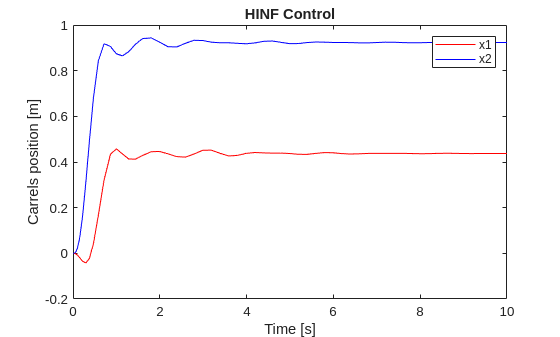


out = sim('Bait_Ambrosino_hinf.slx');
x1_hinf = out.x1.Data;
x2_hinf = out.x2.Data;
time = out.x1.Time;

figure
grid on
plot(time, x1_hinf, 'r', time, x2_hinf, 'b');
xlabel('Time [s]');
ylabel('Carrels position [m]');
title('HINF Control');
legend('x1', 'x2');

Qt = 1e-3*eye(nx)

Qt = 1.0e-03 *

    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


Rt = 1e-4*eye(ny)

Rt = 1.0e-04 *

    1.0000         0
         0    1.0000



[P,~,~] = care(A',C',Qt,Rt)

P =     0.0002    0.0000   -0.0003   -0.0001
    0.0000    0.0003    0.0002   -0.0001
   -0.0003    0.0002    0.0062   -0.0024
   -0.0001   -0.0001   -0.0024    0.0092


L = (P*C')/R

L = 1.0e-03 *

    0.2120    0.0229
    0.0229    0.2887
   -0.2726    0.2427
   -0.1280   -0.0805



Akf = A-L*C

Akf =    -0.0002   -0.0000    1.0000         0
   -0.0000   -0.0003         0    1.0000
  -35.1059   15.1059   -1.8000    0.8000
   12.5886  -33.4217   -0.6667   -0.3333


Bkf = [B L]

Bkf =          0         0    0.0002    0.0000
         0         0    0.0000    0.0003
    1.0000         0   -0.0003    0.0002
         0    0.8333   -0.0001   -0.0001


Ckf = eye(nx)

Ckf =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Dkf = zeros(nx,size(Bkf,2))

Dkf =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0



if any(real(eig(Akf))>0)
    fpritnf('Il Kalmann Filter è localmente instabile in chiuso\n')
else
    fprintf('Il Kalmann Filter è localmente asintoticamente stabile in chiuso\n')
end

Il Kalmann Filter è localmente asintoticamente stabile in chiuso


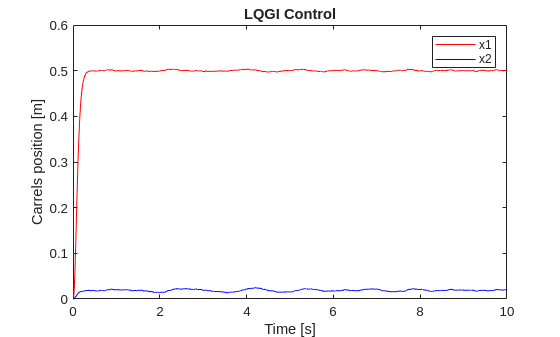



out = sim('Bait_Ambrosino_kf.slx');
x1_kf = out.x1.Data;
x2_kf = out.x2.Data;
time = out.x1.Time;

figure
grid on
plot(time, x1_kf, 'r', time, x2_kf, 'b');
xlabel('Time [s]');
ylabel('Carrels position [m]');
title('LQGI Control');
legend('x1', 'x2');